**EDO-PVI**

% dy/dt = -y*sin(t)
% y(0) = 1
h = 1, ti = 0, tf = 4

h = 1

ti = 0

tf = 4

**Solución Exacta:**

syms y(t)
Dy = diff(y,t);
sol = dsolve(Dy == -y*sin(t),y(0)==1)

$$sol = {\mathrm{e}}^{\cos\left(t\right)}\,{\mathrm{e}}^{-1}$$

sol = matlabFunction(sol)

sol = function_handle with value:
    @(t)exp(cos(t)).*exp(-1.0)


tt = ti:0.1:tf; tt = tt'

tt =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


yexac = sol(tt)

yexac =     1.0000
    0.9950
    0.9803
    0.9563
    0.9241
    0.8848
    0.8397
    0.7904
    0.7384
    0.6850


**Método de Euler:**

% function [t,y_euler] = euler(f,[ti tf],y0,h)
f = @(t,y) -y*sin(t);
ti = 0, tf = 4, y0 = 1, h = 1

ti = 0

tf = 4

y0 = 1

h = 1

% Método euler:
tt2 = ti:h:tf; tt2 = tt2';
y_euler = zeros(size(tt2));
y_euler(1,1) = y0; % CI
for i=1:length(tt2)-1
    y_euler(i+1,1) = y_euler(i,1) + h*f(tt2(i,1),y_euler(i,1));
end
[tt2 y_euler]

ans =          0    1.0000
    1.0000    1.0000
    2.0000    0.1585
    3.0000    0.0144
    4.0000    0.0123


**Método de RK2 (Heun):**

% function [t,y_rk2] = rk2(f,[ti tf],y0,h)
f = @(t,y) -y*sin(t);
ti = 0, tf = 4, y0 = 1, h = 1

ti = 0

tf = 4

y0 = 1

h = 1

% Método rk2:
tt2 = ti:h:tf; tt2 = tt2';
y_rk2 = zeros(size(tt2));
y_rk2(1,1) = y0; % CI
for i=1:length(tt2)-1
    k1 = f(tt2(i,1),y_rk2(i,1));
    k2 = f(tt2(i+1,1),y_rk2(i,1)+h*k1);
    y_rk2(i+1,1) = y_rk2(i,1) + h*(0.5*k1 + 0.5*k2);
end
[tt2 y_rk2]

ans =          0    1.0000
    1.0000    0.5793
    2.0000    0.2938
    3.0000    0.1583
    4.0000    0.1986


**Método de RK4:**

% function [t,y_rk4] = rk4(f,[ti tf],y0,h)
f = @(t,y) -y*sin(t);
ti = 0, tf = 4, y0 = 1, h = 1

ti = 0

tf = 4

y0 = 1

h = 1

% Método rk4:
tt2 = ti:h:tf; tt2 = tt2';
y_rk4 = zeros(size(tt2));
y_rk4(1,1) = y0; % CI
for i=1:length(tt2)-1
    k1 = f(tt2(i,1),y_rk4(i,1));
    k2 = f(tt2(i,1) + 0.5*h, y_rk4(i,1) + 0.5*h*k1);
    k3 = f(tt2(i,1) + 0.5*h, y_rk4(i,1) + 0.5*h*k2);
    k4 = f(tt2(i,1) + h, y_rk4(i,1) + h*k3);
    y_rk4(i+1,1) = y_rk4(i,1) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
end
[tt2 y_rk4]

ans =          0    1.0000
    1.0000    0.6296
    2.0000    0.2434
    3.0000    0.1366
    4.0000    0.1910


**Gráfico Comparativo:**

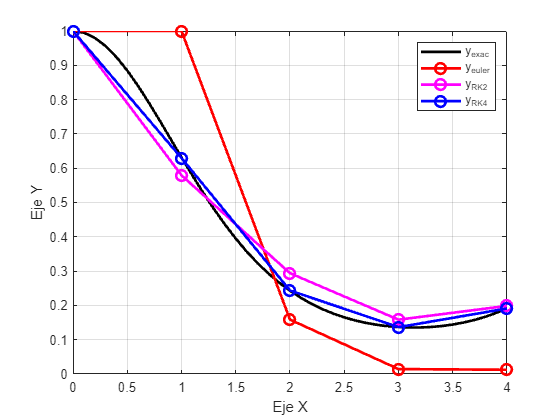

figure(1); clf;
plot(tt,yexac,'-k','LineWidth',2); grid on; hold on;
plot(tt2,y_euler,'-or','LineWidth',2,'MarkerSize',8);
plot(tt2,y_rk2,'-om','LineWidth',2,'MarkerSize',8);
plot(tt2,y_rk4,'-ob','LineWidth',2,'MarkerSize',8);
xlabel('Eje X'); ylabel('Eje Y')
legend('y_{exac}','y_{euler}','y_{RK2}','y_{RK4}')